# **Creating an MDP MATLAB Environment with a Q learning Agent**

**In this module you will learn how to :**

-  Create an MDP Predefined MATLAB Environment

-  Extract and modify properties of the Environment

-  Define and initialize a Q-learning agent (Manually and using Reinforcement Learning toolbox)

-  Define training parameters 

-  Extract Q-table and see how the values are updated according to Bellman Equation.

## Problem Formulation

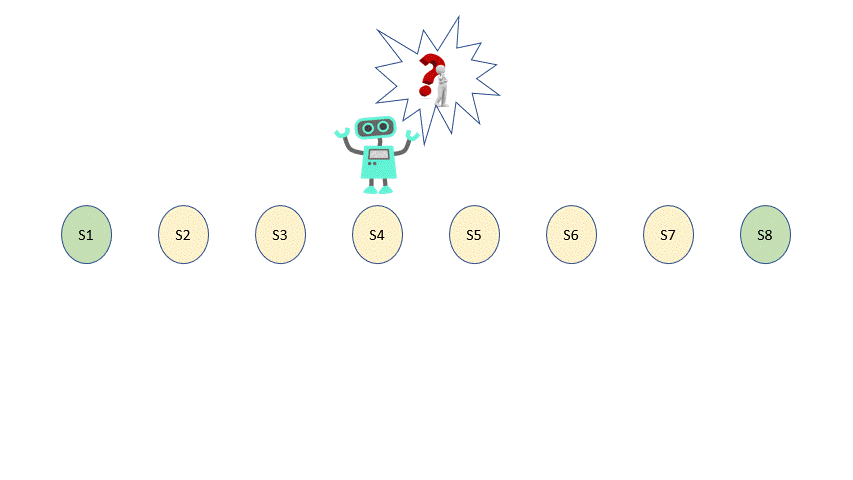

***GOAL****:-* Reach to the *nearest terminal point* *as quickly as possible*

***Action:-***  The agent can either move towards left or right

***States:*** A total of 8 states with 2 terminal states and 6 non terminal states

***Reward:*** All nonterminal states have a small negative reward and terminal states have a large positive reward

***Assumptions:***

- Agent has to move around, cannot stop at one place.

- All actions are deterministic and result into exact execution.

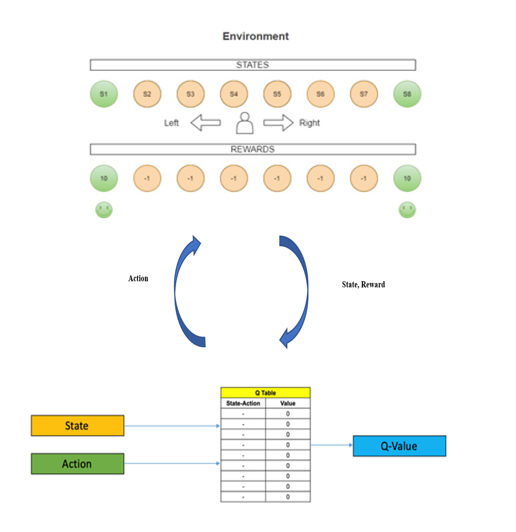

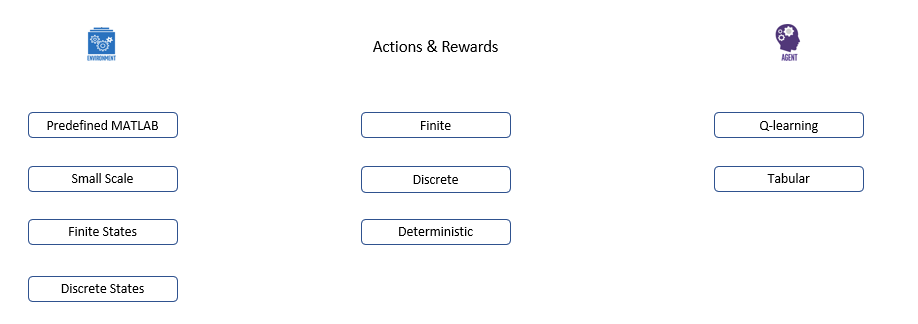

## **Create an MDP Template**

We begin by creating parameters which would be used later at multiple places.

number_states = 8;

% Actions an agent can take
Moves = ["left";"right"];

%Reward for Non-terminal States
RewardNT = -1;

%Reward for Terminal States
RewardT = 10;

%Transition Probability is 1 for all action
Transition_Probability = 1;

We start with creating an envinronment using function [`createMDP(states,actions)`](https://www.mathworks.com/help/reinforcement-learning/ref/createmdp.html#d123e1992)`,`which takes in 2 inputs.

The properties of the environment can be accessed by 'dot' notation. 

MDP = createMDP(number_states,Moves)

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [0×1 string]


MDP.States

ans = 8×1 string array
    "s1"
    "s2"
    "s3"
    "s4"
    "s5"
    "s6"
    "s7"
    "s8"


Actions — Action names, specified as a string vector. 

MDP.Actions

ans = 2×1 string array
    "left"
    "right"


T — State transition matrix, specified as a 3-D array, which determines the possible movements of the agent in an environment.

State transition matrix T is a probability matrix that indicates how likely the agent will move from the current state s to any possible next state s' by performing action a. T is given by, T s, s′, a   =  probability s′ s, a

Eg:- Probability of transitioning from State 2 to State 3 is represented by an element in row 2 and column 3

MDP.T

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


R —  Reward transition matrix, specified as a 3-D array, determines how much reward the agent receives after performing an action in the environment. R has the same shape and size as state transition matrix T. Reward transition matrix R is given by, r  =  R s, s′, a . 

MDP.R

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


## Define Terminal States, Rewards and Transition Probabilities as per given the model

We need to modify certain properties the MDP, according to our model.

#### Modification 1 -- Terminal States

State 1 and 8 [S1 and S8] are the terminal state.

MDP.TerminalStates = ["s1";"s8"]

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [2×1 string]


NonTerminalstates = setdiff(MDP.States, MDP.TerminalStates)

NonTerminalstates = 6×1 string array
    "s2"
    "s3"
    "s4"
    "s5"
    "s6"
    "s7"


#### Modification 2 -- Rewards

We want to have reward of -1 for all the action in all the states except the terminal states, for which the reward is +10

MDP.R(:,:,:) = RewardNT

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [2×1 string]


MDP.R(:,state2idx(MDP,MDP.TerminalStates),:) = RewardT

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [2×1 string]


#### Modification 3 -- Transition Probabilities

Recall the definition of Transition Probability - T s, s′, a   =  probability s′ s, a

Meaning, the probability of going to state s' given the agent is in the state S and takes an action A

eg: In our model, for state 2 the agent should land in state 3 by taking an action RIGHT. And it should land in the state 1 by taking action LEFT.

The agent lands in the same state if it takes action in the Terminal state that leads to nowhere.

% Transition for terminal states - S1 and S8
MDP.T(1,1,1) = Transition_Probability;
MDP.T(1,2,2) = Transition_Probability;

% State 8 transition
MDP.T(8,7,1) = Transition_Probability;
MDP.T(8,8,2) = Transition_Probability;

To update rest of the transition probabilities it would be easier to create a function. The script to the function can be found in a file named[ Update](matlab:open('./Update_Non_Terminal_Transition.mlx'))`_Non_Terminal_Transition`

A function is a group of statements that together perform a task. In MATLAB, functions are defined in separate files. The name of the file and of the function should be the same. More information on how to define a **function** can be found [here](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html)

Update_Non_Terminal_Transition(MDP, NonTerminalstates,Transition_Probability);

## Display modified properties 

MDP.T

ans = ans(:,:,1) =

     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0


ans(:,:,2) =

     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     1


MDP.R

ans = ans(:,:,1) =

    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10


ans(:,:,2) =

    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10


## Initialize Environment

We use  [`rlMDPEnv(MDP)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.rlmdpenv.html#d123e17882) to create an environment using the MDP object. 

env = rlMDPEnv(MDP)

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GenericMDP]
    ResetFcn: []


Store the value of number of states and actions for further use.

We use built-in MATLAB function numel to get the values. [`n = numel(A)`](https://www.mathworks.com/help/matlab/ref/double.numel.html#d123e914058)

number_of_states = numel(MDP.States);
number_of_actions = numel(MDP.Actions);

Save the output as env

save env

This is the first script of this lab. Please [click here](matlab:open('./Agent.mlx')) to move on to the next script `Agent.mlx`